# 1CWK50 submission

Full instructions on how to submit this live script are available in the assignment specification on Moodle ("How to submit your work" section). Make sure you read them carefully, and that you test your final submission thoroughly before uploading it to Moodle. No additional files can be accepted after the deadline has passed.

## 1. Dataset preparation (20%)

% check the dataset is present:
if ~exist('moons.csv', 'file')
    error('You need to download moons.csv from Moodle and place it into the same directory as this live script');
end

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:

% read in the dataset:
data = readcell("moons.csv"); 

%gets observered data by removing headers
obs = data(2:end,:);

%shuffles the observed data
obs_shuffled = obs(randperm(size(obs,1)), :)

obs_shuffled = 150×3 cell array
    {[ 1.9246]}    {[-0.2477]}    {'Class B'}
    {[ 0.4772]}    {[-0.6813]}    {'Class B'}
    {[-0.2362]}    {[ 0.8468]}    {'Class A'}
    {[-0.8506]}    {[ 0.8255]}    {'Class A'}
    {[-1.6224]}    {[ 0.8345]}    {'Class A'}
    {[-0.6959]}    {[ 0.4852]}    {'Class A'}
    {[ 2.4383]}    {[ 0.1484]}    {'Class B'}
    {[ 0.7619]}    {[-0.3577]}    {'Class B'}
    {[ 1.5577]}    {[ 0.0354]}    {'Class B'}
    {[ 1.8496]}    {[ 0.2436]}    {'Class B'}
    {[ 1.9984]}    {[ 0.2602]}    {'Class B'}
    {[ 1.3446]}    {[-0.3832]}    {'Class B'}
    {[ 1.3088]}    {[ 0.7262]}    {'Class A'}
    {[-0.6282]}    {[ 0.8368]}    {'Class A'}
    {[ 1.6078]}    {[ 0.2092]}    {'Class B'}
    {[-0.9977]}    {[ 0.7601]}    {'Class A'}



%finds 40% of the dobservered shuffled data
nTest = round(0.4 * size(obs_shuffled,1));

%splits the data so that 40% is testing data and the remaining 60 is
%training
obs_test = obs_shuffled(1:1:nTest, :);
obs_train = obs_shuffled(nTest+1:1:end, :);

% set the column index of the target feature values
label_index = 3;

% separate the examples and the labels for the testing observations:
test_labels = categorical(obs_test(:, label_index));
test_examples = cell2mat(obs_test(:, 1:end~=label_index));

% separate the examples and the labels for the training observations:
train_labels = categorical(obs_train(:, label_index));
train_examples = cell2mat(obs_train(:, 1:end~=label_index));


## 2. Feature space visualisation (20%)

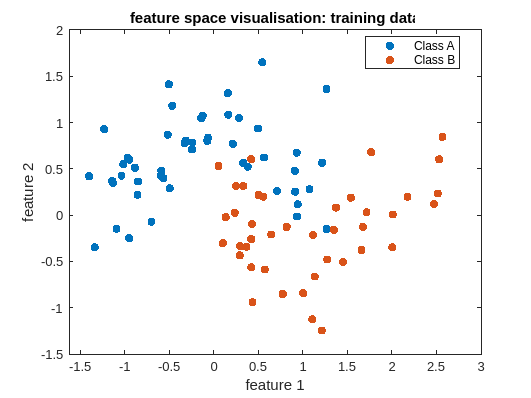

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:

%train a naive bayes classifier 
m_nb = fitcnb(train_examples,train_labels);

%plots gscatter graph for training data
figure; gscatter(m_nb.X(:,1),m_nb.X(:,2),m_nb.Y);

%lable axsis
title('feature space visualisation: training data');
xlabel('feature 1');
ylabel('feature 2');

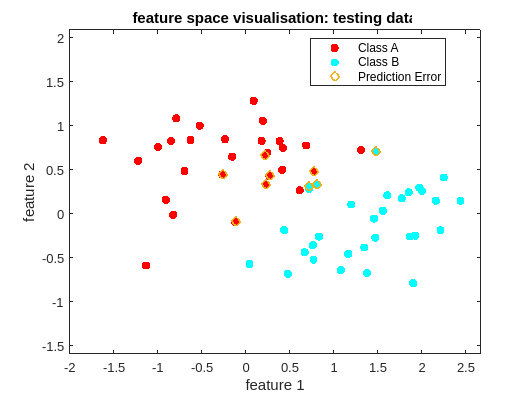


%calls predictions fuction to generate predictions 
predictions = m_nb.predict(test_examples);

%plots the predicted training data 
figure; gscatter(test_examples(:,1),test_examples(:,2),predictions,"rc");


%allows the next plot to be put on the same axis 
axis('equal');
hold("on");

%creates a map of 1,0 : 1 meaning the prediciton doesnt match the result
incorrect_mask = predictions ~= test_labels;
incorrect_examples = [];

%goes through the predictions and plots s circle on top of the incorrect one   
for i = 1:length(incorrect_mask)
    if incorrect_mask(i) ==  1
        incorrect_examples = cat(1,incorrect_examples,test_examples(i,:));
    end
end

scatter(incorrect_examples(:,1),incorrect_examples(:,2),"DisplayName","Prediction Error",LineWidth=1.5);

%plot axis 
xlabel('feature 1');
ylabel('feature 2');
title('feature space visualisation: testing data');

## 3. Abstraction visualisations (20%)

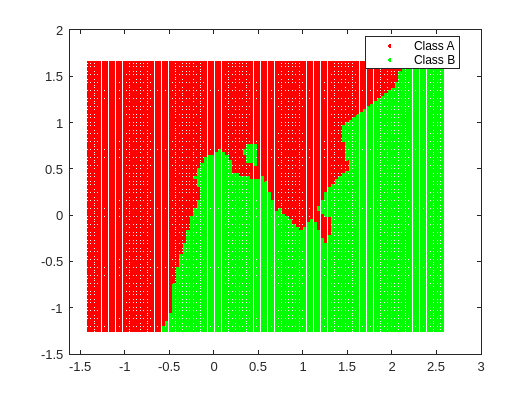

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:

%trains a knn models with then plot a graphical abstraction of the predction model 
m_knn = fitcknn(train_examples,train_labels , 'NumNeighbors', 1);
visualise_abstraction(m_knn);

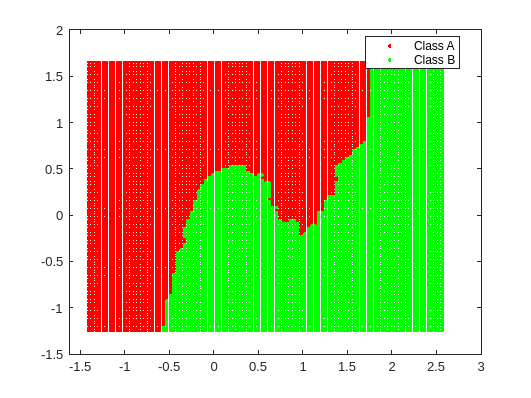


%changes K in Knn to 5 then plot a graphical abstraction of the predction model 
m_knn.NumNeighbors = 5;
visualise_abstraction(m_knn);

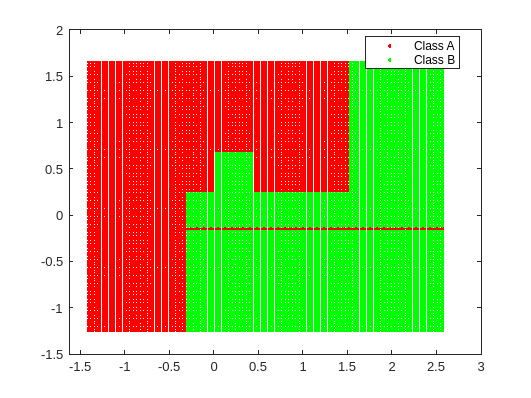


%trains a Decision Tree models with then plot a graphical abstraction of the predction mode
m_dt = fitctree(train_examples, train_labels, 'MergeLeaves', 'off', 'Prune', 'off','MinParentSize',10);
visualise_abstraction(m_dt);

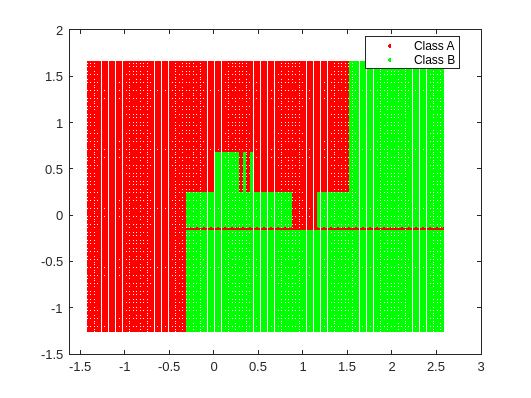


m_dt = fitctree(train_examples, train_labels, 'MergeLeaves', 'off', 'Prune', 'off','MinParentSize',1);
visualise_abstraction(m_dt);

## 4. Classifier re-implementations (20%)

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:
%trains a self implemented knn model  plot a graphical abstraction of the predction mode
mym_knn = my_fitcknn(train_examples, train_labels, 'NumNeighbors', 5);
visualise_abstraction(mym_knn);

## 5. Extension to ensembles (20%)

rng(0); % re-seed the random number for reproducible results

% add your code on the lines below:

%trains a self implemented soft voting ensemble then plots a graphical abstraction of the predction mode
my_en = my_fitcensemble(train_examples, train_labels, 'NumNeighbors', 5);

Unable to perform assignment because value of type 'my_ClassificationKNN' is not convertible to 'double'.

Error in my_fitcensemble (line 14)
        models(end+1 )= my_fitcknn(train_examples,train_labels,"NumNeighbors" , p.Results.NumNeighbors);

Caused by:
    Error using double
    Conversion to double from my_ClassificationKNN is not possible.

visualise_abstraction(my_en);


